A variation on Pipeline Part 6 that checks what happens when the maintenance reaction is turned off in a 2d environment.

data file saved as dat_no_maint.mat

%Temporary / diagnostic changes

%change amount of initial enzyme
%args.p6.v.initenzyme = args.p6.v.initenzyme * 1000

args.p6.v.maxspacebiomass = 1e8;

%remove enzyme decay
args.p6.v.enzdecayperhour = 0;

args.p6.v.drainatedges = false;

args.p6.v.maxcycles = 2000;
args.p6.v.timestep = 5;

args.p6.v.alpha = exp(-4);
args.p6.v.alpha = 0; %turn off enzyme production

args.p6.v.numExRxnSubsteps = 1;

args.p6.v.xdim = 5;
args.p6.v.ydim = 5;

args.p6.v.lograte = 5;

if ~exist('remcfg','var')
    load remoteconfig;
end

initenzyme = [1e-2 1e-5 1e-9];

args.p6.distances = 0;

timesteplengths = args.p6.v.timestep;
duration = args.p6.v.maxcycles * args.p6.v.timestep;

%Remove any lower bounds greater than 0
maintrxns = find(args.p6.model.lb > 0);
if ~isempty(maintrxns)
    args.p6.model.lb(maintrxns) = 0;
    args.p6.model.description = [args.p6.model.description '_noMaintRxn'];
    if ~isfield(args.p6.model,'modifications')
        args.p6.model.modifications = cell(0);
    end
    args.p6.model.modifications = [args.p6.model.modifications {'Removed maintenance reaction lower bounds where lb>0'}];
end

%Generate the COMETS files
[~,layouts_base] = part6_generation_remote(args.p6,remcfg);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

layout_base = layouts_base{1};

%remove the 'cheater' biomass
layout_base.models = layout_base.models(1);
layout_base.initial_pop = 0;
layout_base = setInitialPop(layout_base,'colonies',args.p6.v.initialpop,false);

layouts = cell(length(initenzyme));
for i = 1:length(initenzyme)
    layout_base = setInitialMediaInCell(layout_base,ceil(args.p6.v.xdim/2),ceil(args.p6.v.xdim/2),'enzyme[e]',initenzyme(i));
    layouts{i} = layout_base;
end
[layouts,remcfg,~] = runCometsRemotely(layouts,remcfg);

Creating Comets file batch 190408155808
Use this to instantiate the SSH Agent:
eval `ssh-agent`;ssh-add C:/sync/biomes/scripts/remote/keys/id_rsa_noprompt
 
Execute the following to copy files to remote, or run pushcomets.sh:
scp -r ./190408155808 mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190408155808
 
Execute the following to execute COMETS, or run runremotecomets.sh:
ssh mquintin@scc1 'qsub /usr3/graduate/mquintin/cometsremote/190408155808/cometsremote.sh'
 
Execute the following after run completion to recieve output logs, or run pullcomets.sh:
scp -r mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190408155808/* ./190408155808
 
Remember to kill the SSH Agent when you're done (remember to use 'ps aux' to find stray agents:
kill $SSH_AGENT_ID


%Run the push/execute/pull scripts here
% % system('bash C:/sync/biomes/cellulose/optima/temp/pushcomets.sh')
% % system('bash C:/sync/biomes/cellulose/optima/temp/runremotecomets.sh')
% % system('bash C:/sync/biomes/cellulose/optima/temp/pullcomets.sh')


%Load the results and apply to dat6nm
batchnum = remcfg.batchnum

batchnum = '190408155808'

dat6nm = part6_parseRemoteResults(layouts,batchnum);

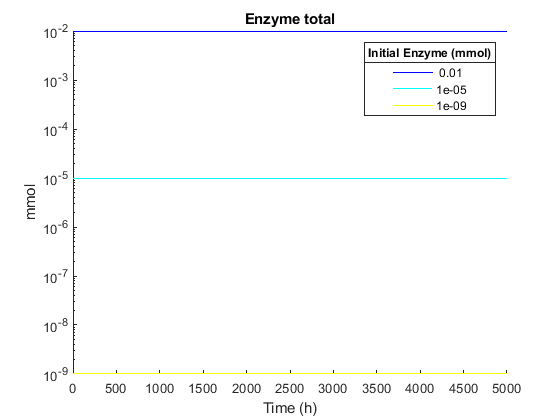

[nrows,ncols] = size(dat6nm);
colors = lines(nrows);
figure();
hold on;
for i = 1:nrows
    plot(dat6nm.t{i},dat6nm.enz_total{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Enzyme total');
leg = legend(num2str(initenzyme'));
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

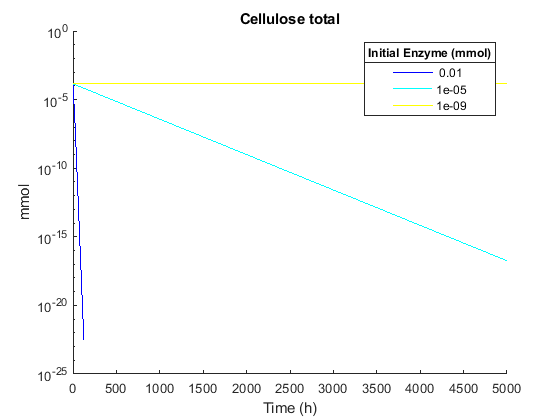


figure();
hold on;
for i = 1:nrows
    plot(dat6nm.t{i},dat6nm.cellulose_total{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Cellulose total');
leg = legend(num2str(initenzyme'));
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

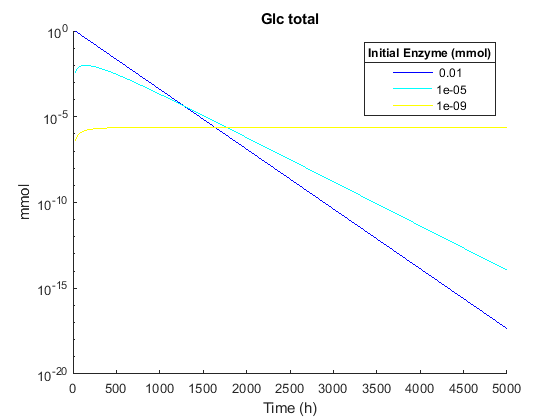


figure();
hold on;
for i = 1:nrows
    plot(dat6nm.t{i},dat6nm.glc_total{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Glc total');
leg = legend(num2str(initenzyme'));
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

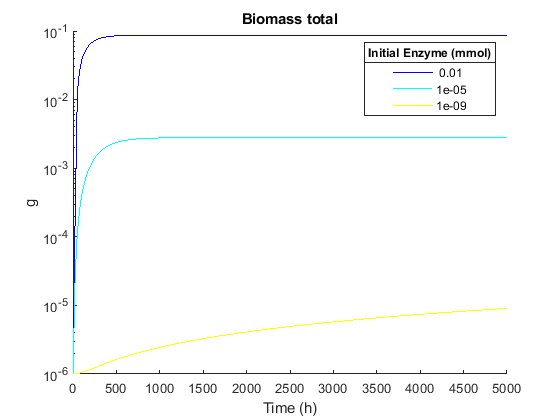


figure();
hold on;
for i = 1:nrows
    plot(dat6nm.t{i},dat6nm.producer_total{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Biomass total');
leg = legend(num2str(initenzyme'));
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('g');

hold off;

## Section 2

Compare data including and excluding maintenance

Uses data from the no_enzyme_decay script (saved as dat_no_enzyme_decat.mat)

datcomb = vertcat(dat6nm,dat6nd);
colors = vertcat(lines(3),lines(3));
linetypes = {'-' '-' '-' '--' '--' '--'};

linetypes = 1×6 cell array
    {'-'}    {'-'}    {'-'}    {'--'}    {'--'}    {'--'}

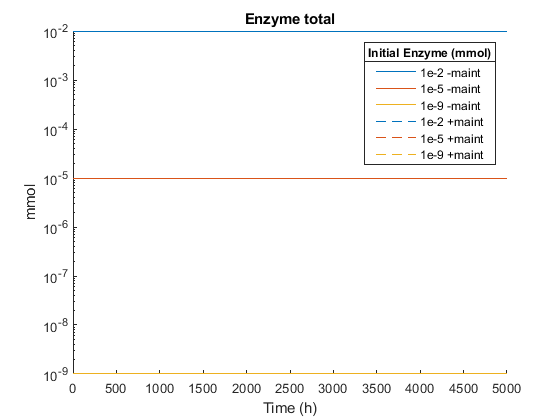

[nrows,ncols] = size(datcomb);
legendstr = {'1e-2 -maint'; '1e-5 -maint'; '1e-9 -maint'; '1e-2 +maint'; '1e-5 +maint'; '1e-9 +maint'};

figure();
hold on;
for i = 1:nrows
    plot(datcomb.t{i},datcomb.enz_total{i},linetypes{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Enzyme total');
leg = legend(legendstr);
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

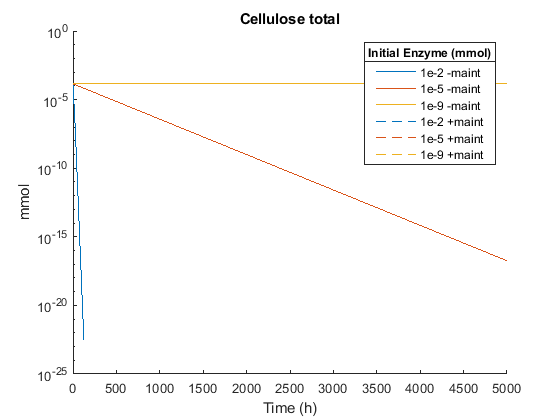


figure();
hold on;
for i = 1:nrows
    plot(datcomb.t{i},datcomb.cellulose_total{i},linetypes{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Cellulose total');
leg = legend(legendstr);
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

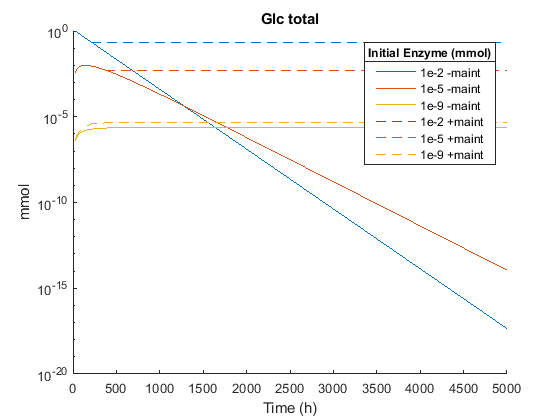


figure();
hold on;
for i = 1:nrows
    plot(datcomb.t{i},datcomb.glc_total{i},linetypes{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Glc total');
leg = legend(legendstr);
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('mmol');

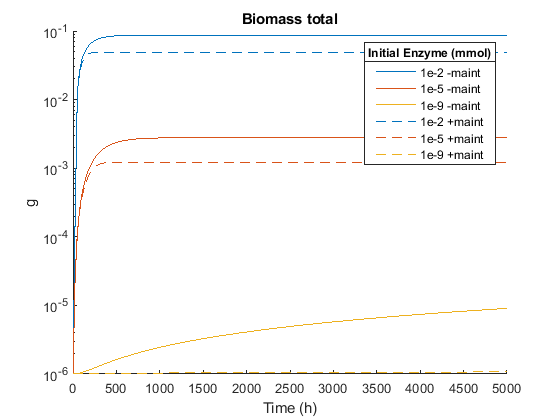


figure();
hold on;
for i = 1:nrows
    plot(datcomb.t{i},datcomb.producer_total{i},linetypes{i},'color',colors(i,:));
end
set(gca,'Yscale','log');
title('Biomass total');
leg = legend(legendstr);
title(leg,'Initial Enzyme (mmol)');
xlabel('Time (h)');
ylabel('g');

hold off;

## Section 3

Observe behavior with enzyme production turned on, and maintenance turned off

alphas = [exp(-2) exp(-4.5) exp(-7)];
args.p6.v.initenzyme = 1e-9;
args.p6.v.enzdecayperhour = 0;

%Generate the COMETS files
[~,layouts_base] = part6_generation_remote(args.p6,remcfg);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

layout_base = layouts_base{1};

%remove the 'cheater' biomass
layout_base.models = layout_base.models(1);
layout_base.initial_pop = 0;
layout_base = setInitialPop(layout_base,'colonies',args.p6.v.initialpop,false);

layouts = cell(length(alphas));
%change the rate of enzyme secretion for each alpha
for i = 1:length(alphas)
    model = layout_base.models{1};
    objidx = find(model.c);
    idx_c = stridx('enzyme[c]',model.mets);
    idx_e = stridx('enzyme[e]',model.mets);
    model.S(idx_c,objidx) = -alphas(i);
    model.S(idx_e,objidx) = alphas(i);
    model.v.alpha = alphas(i);
    layout_base.models{1} = model;
    layouts{i} = layout_base;
end
[layouts,remcfg,~] = runCometsRemotely(layouts,remcfg);

Creating Comets file batch 190416115910
Use this to instantiate the SSH Agent:
eval `ssh-agent`;ssh-add C:/sync/biomes/scripts/remote/keys/id_rsa_noprompt
 
Execute the following to copy files to remote, or run pushcomets.sh:
scp -r ./190416115910 mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190416115910
 
Execute the following to execute COMETS, or run runremotecomets.sh:
ssh mquintin@scc1 'qsub /usr3/graduate/mquintin/cometsremote/190416115910/cometsremote.sh'
 
Execute the following after run completion to recieve output logs, or run pullcomets.sh:
scp -r mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190416115910/* ./190416115910
 
Remember to kill the SSH Agent when you're done (remember to use 'ps aux' to find stray agents:
kill $SSH_AGENT_ID


%Load the results and apply to dat6nm
batchnum = remcfg.batchnum

batchnum = '190409182506'

dat6nmep = part6_parseRemoteResults(layouts,batchnum);

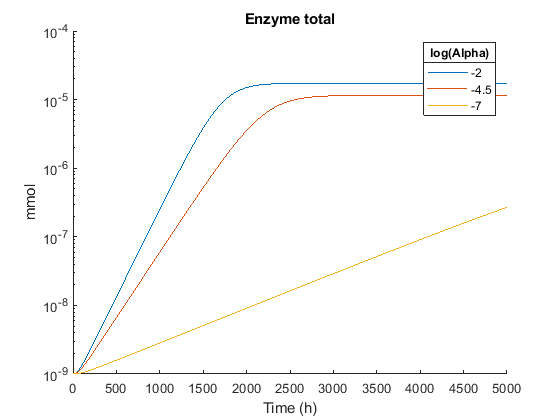

[nrows,ncols] = size(dat6nmep);
colors = lines(nrows);
figure();
hold on;
for i = 1:nrows
    plot(dat6nmep.t{i},dat6nmep.enz_total{i},'color',colors(i,:),'DisplayName',num2str(log(dat6nmep.alpha(i))));
end
set(gca,'Yscale','log');
title('Enzyme total');
leg = legend();
title(leg,'log(Alpha)');
xlabel('Time (h)');
ylabel('mmol');

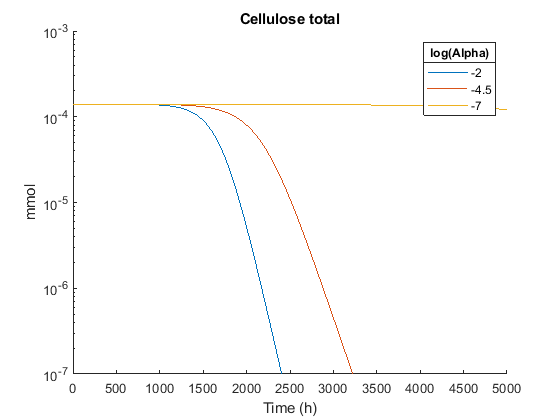


figure();
hold on;
for i = 1:nrows
    plot(dat6nmep.t{i},dat6nmep.cellulose_total{i},'color',colors(i,:),'DisplayName',num2str(log(dat6nmep.alpha(i))));
end
set(gca,'Yscale','log');
title('Cellulose total');
leg = legend();
title(leg,'log(Alpha)');
xlabel('Time (h)');
ylabel('mmol');

ylim([1e-7 1e-3]);

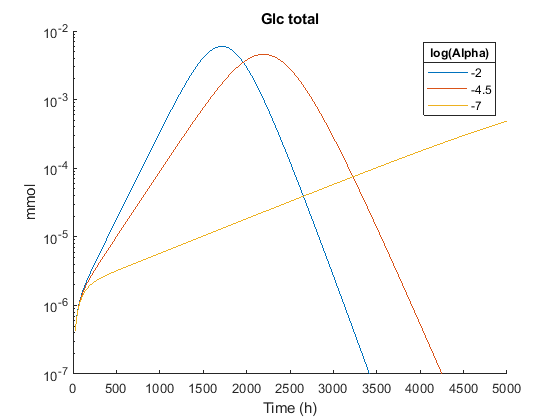


figure();
hold on;
for i = 1:nrows
    plot(dat6nmep.t{i},dat6nmep.glc_total{i},'color',colors(i,:),'DisplayName',num2str(log(dat6nmep.alpha(i))));
end
set(gca,'Yscale','log');
title('Glc total');
leg = legend();
title(leg,'log(Alpha)');
xlabel('Time (h)');
ylabel('mmol');
ylim([1e-7 1e-2]);

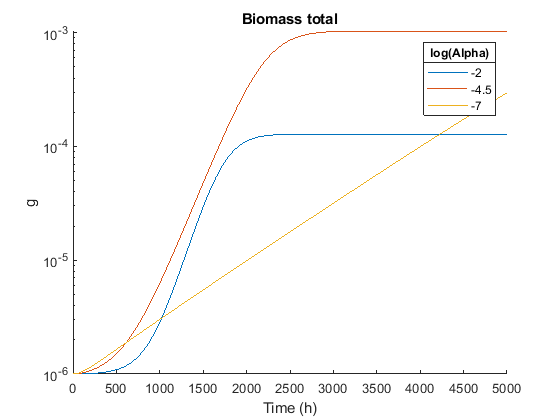


figure();
hold on;
for i = 1:nrows
    plot(dat6nmep.t{i},dat6nmep.producer_total{i},'color',colors(i,:),'DisplayName',num2str(log(dat6nmep.alpha(i))));
end
set(gca,'Yscale','log');
title('Biomass total');
leg = legend();
title(leg,'log(Alpha)');
xlabel('Time (h)');
ylabel('g');

hold off;

## Section 4

Compare a model where the maintenance reaction is set to be maximized instead of forcing by having a minimum > 0

args.p6.v.maxcycles = 1600;
args.p6.v.timestep = 0.5;


%reset the model
args.p6.model = model_default;
%%Following block has been copied to the function maintenanceAsObjective(model)
% %Remove any lower bounds greater than 0
% %then set the objective field to maximize those reactions
% %and set the biomass reaction to the original objective
% maintrxns = find(args.p6.model.lb > 0);
% if ~isempty(maintrxns)
%     args.p6.model.ub(maintrxns) = args.p6.model.lb(maintrxns); %probably not necessary, but in case these were not ==min
%     args.p6.model.lb(maintrxns) = 0;
%     args.p6.model.description = [args.p6.model.description '_noMaintRxn'];
%     if ~isfield(args.p6.model,'modifications')
%         args.p6.model.modifications = cell(0);
%     end
%     args.p6.model.modifications = [args.p6.model.modifications {'Removed maintenance reaction lower bounds where lb>0'}];
%     
%     baseobjs = find(args.p6.model.c);
%     %set the maint rxns as highest priority
%     args.p6.model.objective = zeros(1,length(args.p6.model.rxns));
%     args.p6.model.objective(maintrxns) = 1:length(maintrxns);
%     %set the original objectives as lower priority (high absolute value is low priority)
%     args.p6.model.objective(baseobjs) = args.p6.model.c(baseobjs) * (length(maintrxns) + 1);
%     args.p6.model.modifications = [args.p6.model.modifications {'Added maintenance reaction as primary objective function'}];
%     
%     %set the biomass reaction
%     if ~isfield(args.p6.model,'biomassRxn')
%         args.p6.model.biomassRxn = baseobjs;
%     end
% end
args.p6.model = maintenanceAsObjective(args.p6.model);

alphas = [exp(-2) exp(-4.5) exp(-7)];
initenzyme = [1e-2 1e-5 1e-9];
enzdecayperhour = [0 0.01 0.1];

alphas = [exp(-5) exp(-6) exp(-7) exp(-8) exp(-9)];
alphas = [exp(-2) exp(-3) exp(-4)];
initenzyme = [1e-6 1e-7 1e-8 1e-9];
enzdecayperhour = [0 0.01 0.1];

% alphas = exp(-9);
% initenzyme = 1e-6;
% enzdecayperhour = 0.01;
args.p6.v.timestep = 0.5;
timesteplengths = 0.5;
args.p6.v.maxcycles = 1000;
duration = 500;
%this block: Investigating suspicious growth rate spike at
%A=exp(-9),initenz=1e-6,enzdecay=0.01
%data saved as dat_maintasobjective_exploreA9growthspike
testspikeanomaly = false;
if testspikeanomaly
    alphas = [exp(-8.9) exp(-9) exp(-9.1)];
    initenzyme = [0.95e-6 1e-6 1.05e-6];
    enzdecayperhour = [.0095 0.01 .0105];
    args.p6.v.timestep = .5;
    
    %check the variability just around the timestep length
    alphas = exp(-9);
    initenzyme = 1e-6;
    enzdecayperhour = 0.01;
    timesteplengths = [0.45 .5 .55];
    duration = 500;
end
testspikeanomaly2 = false;
if testspikeanomaly2
    alphas = [exp(-3.95) exp(-4) exp(-4.05)];
    initenzyme = [9.5e-9 1e-8 1.05e-8];
    enzdecayperhour = [0.0105 0.01 0.0095];
    timesteplengths = .5 * [.95 1 1.05];
end
testspikeanomaly3 = true;
if testspikeanomaly3
    alphas = exp(-4);
    initenzyme = 1e-8;
    enzdecayperhour = 0.01;
    timesteplengths = [.49 .5];
    duration = 200;
end


%Generate the COMETS files
[~,layouts_base] = part6_generation_remote(args.p6,remcfg);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

layout_base = layouts_base{1};

%remove the 'cheater' biomass
layout_base.models = layout_base.models(1);
layout_base.initial_pop = 0;
layout_base = setInitialPop(layout_base,'colonies',args.p6.v.initialpop,false);

if testspikeanomaly3
    layout_base.params.biomassLogRate = 1;
    layout_base.params.mediaLogRate = 1;
end

layouts = cell(0);
layoutidx = 0;
%change the rate of enzyme secretion for each alpha
for i = 1:length(alphas)
    for j = 1:length(initenzyme)
        for k = 1:length(enzdecayperhour)
            for t = 1:length(timesteplengths)
                args.p6.v.timestep = timesteplengths(t);
                args.p6.v.maxcycles = ceil(duration / timesteplengths(t));
                
                layoutidx = layoutidx + 1;
                args.p6.v.enzdecayperhour = enzdecayperhour(k);
                args.p6.v.initenzyme = initenzyme(j);
                layout = layout_base;
                layout.external_rxns = table();
                layout.external_rxn_mets = table();
                layout = addExternalReaction(layout,'degrade_cellulose',{'cellulose','glc-D[e]'},[-1 args.p6.v.glcpercellulose],'enzyme', 'enzyme[e]', 'k', args.p6.v.kcat_cel/args.p6.v.glcpercellulose, 'km', args.p6.v.km_cel);
                if args.p6.v.enzdecayperhour ~= 0
                    layout = addExternalReaction(layout,'enzyme_decay','enzyme[e]',-1,'vmax',args.p6.v.enzdecayperhour/3600);
                end
                layout = setInitialMediaInCell(layout,ceil(args.p6.v.xdim/2),ceil(args.p6.v.xdim/2),'enzyme[e]',initenzyme(j));
                model = layout.models{1};
                objidx = find(model.c);
                idx_c = stridx('enzyme[c]',model.mets);
                idx_e = stridx('enzyme[e]',model.mets);
                model.S(idx_c,objidx) = -alphas(i);
                model.S(idx_e,objidx) = alphas(i);
                args.p6.v.alpha = alphas(i);
                model.v = args.p6.v;
                layout.models{1} = model;
                layout.params.maxCycles = args.p6.v.maxcycles;
                layout.params.timeStep = args.p6.v.timestep;
                layouts{layoutidx} = layout;
            end
        end
    end
end
[layouts,remcfg,~] = runCometsRemotely(layouts,remcfg);

Creating Comets file batch 190424144216
Use this to instantiate the SSH Agent:
eval `ssh-agent`;ssh-add C:/sync/biomes/scripts/remote/keys/id_rsa_noprompt
 
Execute the following to copy files to remote, or run pushcomets.sh:
scp -r ./190424144216 mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190424144216
 
Execute the following to execute COMETS, or run runremotecomets.sh:
ssh mquintin@scc1 'qsub /usr3/graduate/mquintin/cometsremote/190424144216/cometsremote.sh'
 
Execute the following after run completion to recieve output logs, or run pullcomets.sh:
scp -r mquintin@scc1:/usr3/graduate/mquintin/cometsremote/190424144216/* ./190424144216
 
Remember to kill the SSH Agent when you're done (remember to use 'ps aux' to find stray agents:
kill $SSH_AGENT_ID


%Load the results
batchnum = remcfg.batchnum

batchnum = '190424144216'

dat6maintasobj_full = part6_parseRemoteResults(layouts,batchnum);
[nrows, ~] = size(dat6maintasobj_full);


%add growthrate and initenz columns
[nrows,~] = size(dat6maintasobj_full)

nrows = 2

for i = 1:nrows
    delta = dat6maintasobj_full.producer_total{i}(2:end) - dat6maintasobj_full.producer_total{i}(1:end-1);
    delta = delta ./ dat6maintasobj_full.producer_total{i}(1:end-1);
    ts = dat6maintasobj_full.t{i}(2) - dat6maintasobj_full.t{i}(1);
    mu = delta / ts;
    dat6maintasobj_full.producer_growthrate{i} = mu;
    
    delta = dat6maintasobj_full.cheater_total{i}(2:end) - dat6maintasobj_full.cheater_total{i}(1:end-1);
    delta = delta ./ dat6maintasobj_full.cheater_total{i}(1:end-1);
    ts = dat6maintasobj_full.t{i}(2) - dat6maintasobj_full.t{i}(1);
    mu = delta / ts;
    dat6maintasobj_full.cheater_growthrate{i} = mu;
    
    dat6maintasobj_full.initenz(i) = dat6maintasobj_full.enz_total{i}(1);
    dat6maintasobj_full.initenz_log10(i) = log10(dat6maintasobj_full.enz_total{i}(1));
end

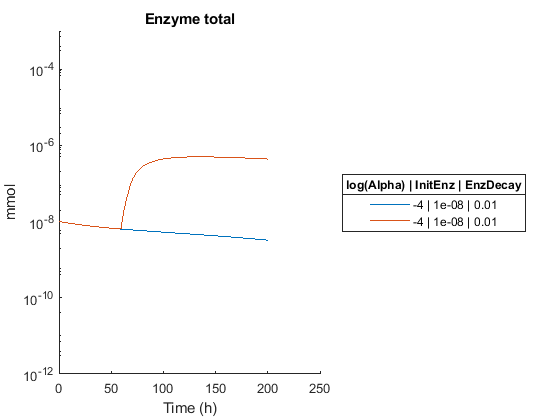

dat6maintasobj = dat6maintasobj_full;
%dat6maintasobj = dat6maintasobj_full(dat6maintasobj_full.decayrate == 0.01,:);
% %dat6maintasobj = dat6maintasobj(dat6maintasobj.initenz == 1e-7 | dat6maintasobj.initenz == 1e-8,:);
% dat6maintasobj = dat6maintasobj(dat6maintasobj.initenz == 1e-6,:);
% dat6maintasobj = dat6maintasobj(dat6maintasobj.alpha == exp(-9),:);

[nrows, ~] = size(dat6maintasobj);

legendlocation = 'best';
legendlocation = 'eastoutside';
[nrows,ncols] = size(dat6maintasobj);
colors = lines(nrows);
figure();
hold on;
for i = 1:nrows
    name = [num2str(log(dat6maintasobj.alpha(i))) ' | ' num2str(dat6maintasobj.enz_total{i}(1)) ' | ' num2str(dat6maintasobj.decayrate(i))];
    plot(dat6maintasobj.t{i},dat6maintasobj.enz_total{i},'color',colors(i,:),'DisplayName',name);
end
set(gca,'Yscale','log');
title('Enzyme total');
leg = legend('location',legendlocation);
title(leg,'log(Alpha) | InitEnz | EnzDecay');
xlabel('Time (h)');
ylabel('mmol');
ylim([1e-12 1e-3]);

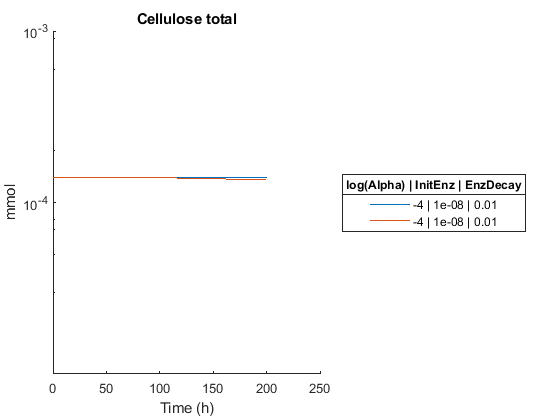


figure();
hold on;
for i = 1:nrows
    name = [num2str(log(dat6maintasobj.alpha(i))) ' | ' num2str(dat6maintasobj.enz_total{i}(1)) ' | ' num2str(dat6maintasobj.decayrate(i))];
    plot(dat6maintasobj.t{i},dat6maintasobj.cellulose_total{i},'color',colors(i,:),'DisplayName',name);
end
set(gca,'Yscale','log');
title('Cellulose total');
leg = legend('location',legendlocation);
title(leg,'log(Alpha) | InitEnz | EnzDecay');
xlabel('Time (h)');
ylabel('mmol');
ylim([1e-5 1e-3]);

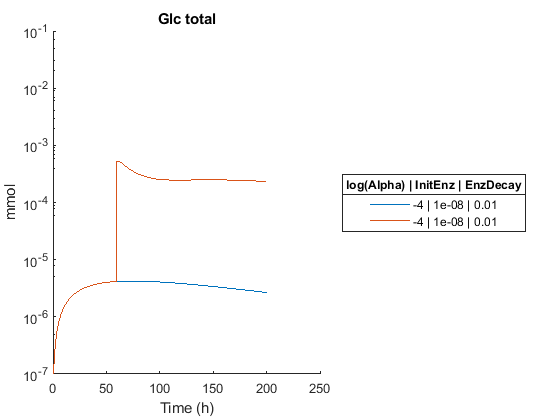


figure();
hold on;
for i = 1:nrows
    name = [num2str(log(dat6maintasobj.alpha(i))) ' | ' num2str(dat6maintasobj.enz_total{i}(1)) ' | ' num2str(dat6maintasobj.decayrate(i))];
    plot(dat6maintasobj.t{i},dat6maintasobj.glc_total{i},'color',colors(i,:),'DisplayName',name);
end
set(gca,'Yscale','log');
title('Glc total');
leg = legend('location',legendlocation);
title(leg,'log(Alpha) | InitEnz | EnzDecay');
xlabel('Time (h)');
ylabel('mmol');
ylim([1e-7 1e-1]);

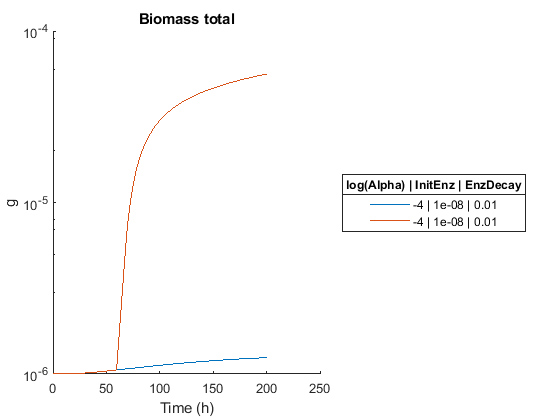


figure();
hold on;
for i = 1:nrows
    name = [num2str(log(dat6maintasobj.alpha(i))) ' | ' num2str(dat6maintasobj.enz_total{i}(1)) ' | ' num2str(dat6maintasobj.decayrate(i))];
    plot(dat6maintasobj.t{i},dat6maintasobj.producer_total{i},'color',colors(i,:),'DisplayName',name);
end
set(gca,'Yscale','log');
title('Biomass total');
leg = legend('location',legendlocation);
title(leg,'log(Alpha) | InitEnz | EnzDecay');
xlabel('Time (h)');
ylabel('g');

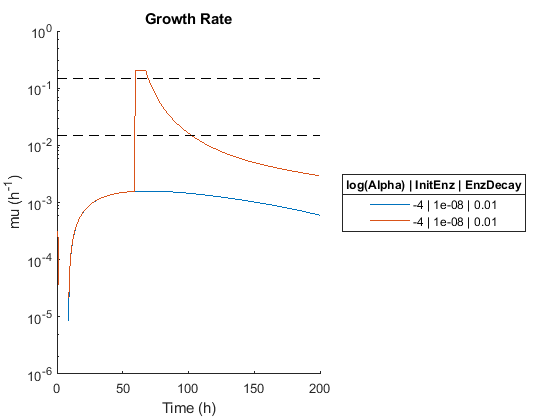

%ylim([1e-6 1e-2]);

figure();
hold on;
for i = 1:nrows
    name = [num2str(log(dat6maintasobj.alpha(i))) ' | ' num2str(dat6maintasobj.enz_total{i}(1)) ' | ' num2str(dat6maintasobj.decayrate(i))];
    plot(dat6maintasobj.t{i}(1:end-1),dat6maintasobj.producer_growthrate{i},'color',colors(i,:),'DisplayName',name);
end
plot(get(gca,'Xlim'),[.15 .15],'--k','HandleVisibility','off');
plot(get(gca,'Xlim'),[.015 .015],'--k','HandleVisibility','off');
set(gca,'Yscale','log');
title('Growth Rate');
leg = legend('location',legendlocation);
title(leg,'log(Alpha) | InitEnz | EnzDecay');
xlabel('Time (h)');
ylabel('mu (h^-^1)');

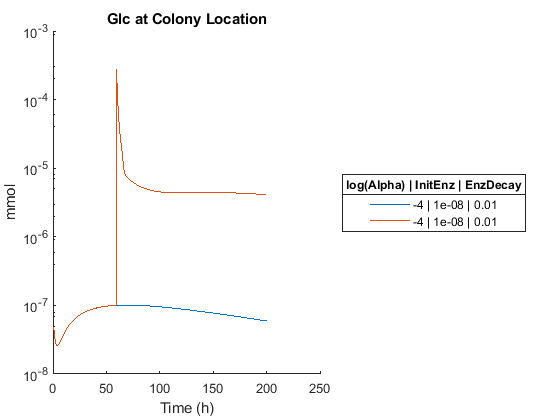

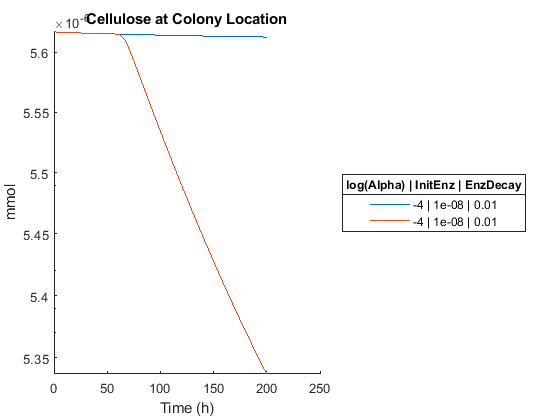

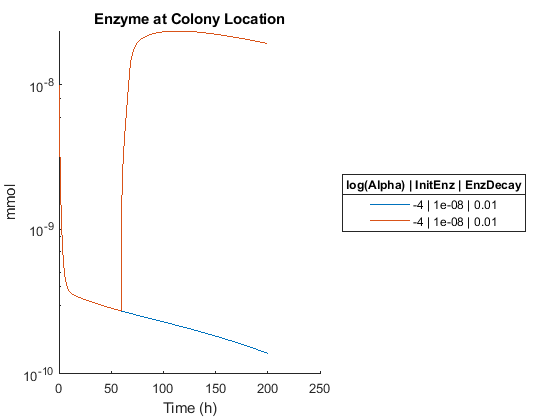

glcspike = 119

biospike = 120

enzspike = 137


plotlocalmedia = true;
if plotlocalmedia
    figure();
    hold on;
    for i = 1:nrows
        name = [num2str(log(dat6maintasobj.alpha(i))) ' | ' num2str(dat6maintasobj.enz_total{i}(1)) ' | ' num2str(dat6maintasobj.decayrate(i))];
        localglc = dat6maintasobj.glc_coord{i}(3,3,:);
        plot(dat6maintasobj.t{i}(1:end),localglc(:),'color',colors(i,:),'DisplayName',name);
    end
    set(gca,'Yscale','log');
    title('Glc at Colony Location');
    leg = legend('location',legendlocation);
    title(leg,'log(Alpha) | InitEnz | EnzDecay');
    xlabel('Time (h)');
    ylabel('mmol');
    
    figure();
    hold on;
    for i = 1:nrows
        name = [num2str(log(dat6maintasobj.alpha(i))) ' | ' num2str(dat6maintasobj.enz_total{i}(1)) ' | ' num2str(dat6maintasobj.decayrate(i))];
        localcel = dat6maintasobj.cellulose_coord{i}(3,3,:);
        plot(dat6maintasobj.t{i}(1:end),localcel(:),'color',colors(i,:),'DisplayName',name);
    end
    set(gca,'Yscale','log');
    title(['Cellulose at Colony Location']);
    leg = legend('location',legendlocation);
    title(leg,'log(Alpha) | InitEnz | EnzDecay');
    xlabel('Time (h)');
    ylabel('mmol');
    
    figure();
    hold on;
    for i = 1:nrows
        name = [num2str(log(dat6maintasobj.alpha(i))) ' | ' num2str(dat6maintasobj.enz_total{i}(1)) ' | ' num2str(dat6maintasobj.decayrate(i))];
        localenz = dat6maintasobj.enz_coord{i}(3,3,:);
        plot(dat6maintasobj.t{i}(1:end),localenz(:),'color',colors(i,:),'DisplayName',name);
    end
    set(gca,'Yscale','log');
    title(['Enzyme at Colony Location']);
    leg = legend('location',legendlocation);
    title(leg,'log(Alpha) | InitEnz | EnzDecay');
    xlabel('Time (h)');
    ylabel('mmol');
    
    row = dat6maintasobj(2,:);
    glcspike = find(row.glc_delta{1} == max(row.glc_delta{1}))
    biospike = find(row.producer_growthrate{1} == max(row.producer_growthrate{1}))
    enzspike = find(row.enz_delta{1} == max(row.enz_delta{1}))
    figure();
    plot(1:length(row.glc_delta{1}),row.glc_delta{1}/max(row.glc_delta{1}),1:length(row.producer_growthrate{1}),row.producer_growthrate{1}/max(row.producer_growthrate{1}),1:length(row.enz_delta{1}),row.enz_delta{1}/max(row.enz_delta{1}))
    legend({'glc delta';'growthrate';'enz delta'});
    

end

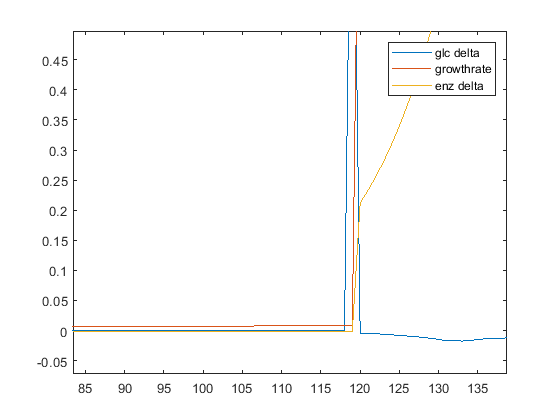


hold off;